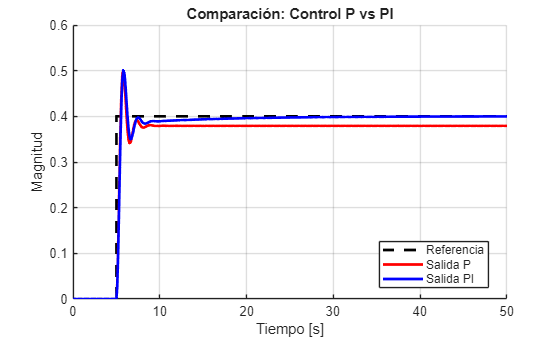

function Ts = settling_time(t, y, y_ss, tol)
    % Last time out of bounds (index)
    idx_last_out = find(abs(y - y_ss) > tol, 1, 'last');

    if isempty(idx_last_out)
        Ts = t(1); % Never out of bounds
    elseif idx_last_out == numel(t)
        Ts = NaN;  % Never stable
    else
        Ts = t(idx_last_out + 1);
    end
end

% P controller
Kp_P = 90;
h0   = 0;
NumK = [Kp_P];
DenK = [1];
outP = sim("Controlador.mdl");

% PI controller
Kp_PI = 80;
Ti_PI = 10;
h0    = 0;
NumK  = Kp_PI * [Ti_PI 1];
DenK  = [Ti_PI 0];
outPI = sim("Controlador.mdl");

% Plot
figure;
hold on;
grid on;
plot(outPI.ref.Time, outPI.ref.Data, "k--", "LineWidth", input_signal_linewidth);
plot(outP.y.Time,   outP.y.Data,   "r-", "LineWidth", output_signal_linewidth);   % P 
plot(outPI.y.Time,  outPI.y.Data,  "b-", "LineWidth", output_signal_linewidth);   % PI
title("Comparación: Control P vs PI");
xlabel("Tiempo [s]");
ylabel("Magnitud");
legend("Referencia", "Salida P", "Salida PI", "Location", "Best");
hold off;


% Analitical Analysis
ref_ss = outPI.ref.Data(end); % Steady State Reference
yP_ss  = outP.y.Data(end);    % Steady State P Controller
yPI_ss = outPI.y.Data(end);   % Steady State PI Controller
% Absolute steady-state errors
errP_ss  = abs(ref_ss - yP_ss);
errPI_ss = abs(ref_ss - yPI_ss);
% Maximum values
yP_max  = max(outP.y.Data);
yPI_max = max(outPI.y.Data);
% Settling time
tol_rel = 0.02;
tol_abs = tol_rel * abs(ref_ss);
Ts_P2   = settling_time(outP.y.Time,  outP.y.Data,  yP_ss,  tol_abs);
Ts_PI2  = settling_time(outPI.y.Time, outPI.y.Data, yPI_ss, tol_abs);
tol_rel = 0.05;
tol_abs = tol_rel * abs(ref_ss);
Ts_P5   = settling_time(outP.y.Time,  outP.y.Data,  yP_ss,  tol_abs);
Ts_PI5  = settling_time(outPI.y.Time, outPI.y.Data, yPI_ss, tol_abs);

fprintf("=== Métricas Control P ===\n");

=== Métricas Control P ===


fprintf("  Valor máximo        : %.4f\n", yP_max);

  Valor máximo        : 0.5000


fprintf("  Error estacionario  : %.4f\n\n", errP_ss);

  Error estacionario  : 0.0207



fprintf("  Ts 2 (P)            : %.4f s\n", Ts_P2);

  Ts 2 (P)            : 7.6000 s


fprintf("  Ts 5 (P)            : %.4f s\n", Ts_P5);

  Ts 5 (P)            : 6.9000 s



fprintf("=== Métricas Control PI ===\n");

=== Métricas Control PI ===


fprintf("  Valor máximo        : %.4f\n", yPI_max);

  Valor máximo        : 0.5009


fprintf("  Error estacionario  : %.4f\n\n", errPI_ss);

  Error estacionario  : 0.0002



fprintf("  Ts 2 (PI)           : %.4f s\n", Ts_PI2);

  Ts 2 (PI)           : 12.7000 s


fprintf("  Ts 5 (PI)           : %.4f s\n", Ts_PI5);

  Ts 5 (PI)           : 7.1000 s
